clear; addpath('Waveforms\HelperFuncs\')

## Load Waveform Config

vars = load("Waveforms\16QAMv3\vars.mat");
waveconfig = vars.cfgDL;
waveform = vars.waveform;
waveInfo = vars.info;



## Load data

rxWaveform = load('gnudata\received_03Mar151930QPSKx4_Ref.mat','data');
rxWaveform = rxWaveform.data;
% rxWaveform = waveform;
sampleRate = waveInfo.ResourceGrids.Info.SampleRate;
[p, q] = rat(sampleRate/(200e6/6),1e-7); % Resample to the Nominal Sample rate 30.72Mhz
rxWaveform = resample(rxWaveform,p,q);
% rxWaveform = rxWaveform(1:307200);


## Params for SSB Block

fPhaseComp = waveconfig.CarrierFrequency;
minChannelBW = 5;
refBurst.BlockPattern = waveconfig.SSBurst.BlockPattern;
refBurst.L_max = 8;

nrbSSB = 20;  % Number od Resource Blocks for SSBurst.
scsSSB = hSSBurstSubcarrierSpacing(refBurst.BlockPattern);
rxOfdmInfo = nrOFDMInfo(nrbSSB,scsSSB,'SampleRate',sampleRate)

rxOfdmInfo = struct with fields:
                   Nfft: 1024
             SampleRate: 30720000
    CyclicPrefixLengths: [88 72 72 72 72 72 72 72 72 72 72 72 72 72 88 72 72 72 72 72 72 72 72 72 72 72 72 72]
          SymbolLengths: [1112 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1112 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096 1096]
              Windowing: 36
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 2
          SlotsPerFrame: 20


## Visualize

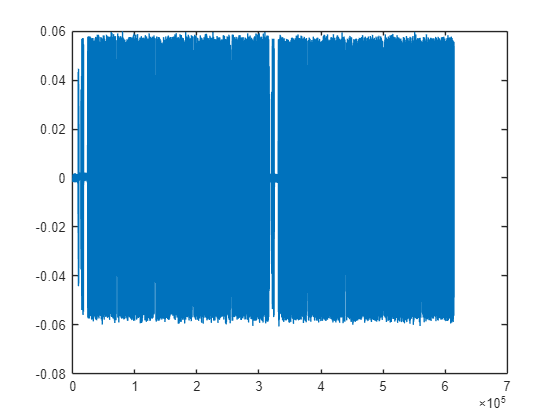

plot(real(rxWaveform));

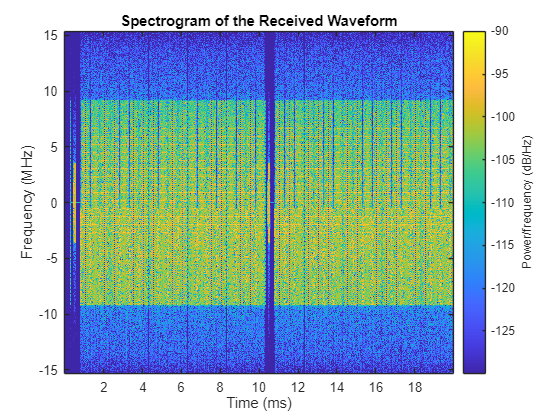

figure;
nfft = rxOfdmInfo.Nfft;
spectrogram(rxWaveform(:,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of the Received Waveform')

## Frequency and Timining Offset Corrections and Primary Sync Signal (PSS) Block Search andProcessing

Correlate the frequency-shifted received waveform with each of the three possible PSS sequences (NID2) and extract the strongest correlation peak. The reference PSS sequences are centered in frequency. Therefore, the strongest correlation peak provides a measure of coarse frequency offset with respect to the center frequency of the carrier. The peak also indicates which of the three PSS (NID2) has been detected in the received waveform and the time instant of the best channel conditions.

disp(' -- Frequency correction and timing estimation --')

 -- Frequency correction and timing estimation --


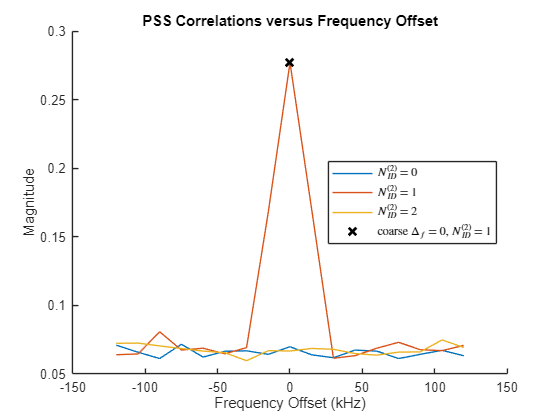

% Specify the frequency offset search bandwidth in kHz
searchBW = 8*scsSSB;  %Seacrh Space for timing offset
[rxWave,freqOffset,NID2] = hSSBurstFrequencyCorrect(rxWaveform,refBurst.BlockPattern,sampleRate,searchBW);  % FO Compensation

disp([' Frequency offset: ' num2str(freqOffset,'%.0f') ' Hz'])

 Frequency offset: 11 Hz


% Create a reference grid for timing estimation using detected PSS. The PSS
% is placed in the second OFDM symbol of the reference grid to avoid the
% special CP length of the first OFDM symbol.
refGrid = zeros([nrbSSB*12 2]);
refGrid(nrPSSIndices,2) = nrPSS(NID2); % Second OFDM symbol for correct CP length

% Timing estimation. This is the timing offset to the OFDM symbol prior to
% the detected SSB due to the content of the reference grid
nSlot = 0;
timingOffset = nrTimingEstimate(rxWave,nrbSSB,scsSSB,nSlot,refGrid,'SampleRate',sampleRate);

% Synchronization, OFDM demodulation, and extraction of strongest SS block
rxGrid = nrOFDMDemodulate(rxWave(1+timingOffset:end,:),nrbSSB,scsSSB,nSlot,'SampleRate',sampleRate);
rxGrid = rxGrid(:,2:5,:);

% Display the timing offset in samples. As the symbol lengths are measured
% in FFT samples, scale the symbol lengths to account for the receiver
% sample rate.
srRatio = sampleRate/(scsSSB*1e3*rxOfdmInfo.Nfft);
firstSymbolLength = rxOfdmInfo.SymbolLengths(1)*srRatio;
str = sprintf(' Time offset to synchronization block: %%.0f samples (%%.%.0ff ms) \n',floor(log10(sampleRate))-3);
fprintf(str,timingOffset+firstSymbolLength,(timingOffset+firstSymbolLength)/sampleRate*1e3);

 Time offset to synchronization block: 13042 samples (0.4245 ms) 


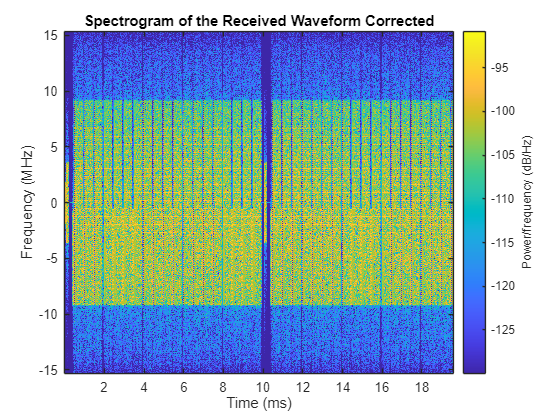

figure;
nfft = rxOfdmInfo.Nfft;
spectrogram(rxWaveform(1+timingOffset:end,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of the Received Waveform Corrected')

## Secondary Sync Signal Block Search and Processing

The receiver extracts the resource elements associated to the SSS from the received grid and correlates them with each possible SSS sequence generated locally. The indices of the strongest PSS and SSS sequences combined give the physical layer cell identity, which is required for PBCH DM-RS and PBCH processing.

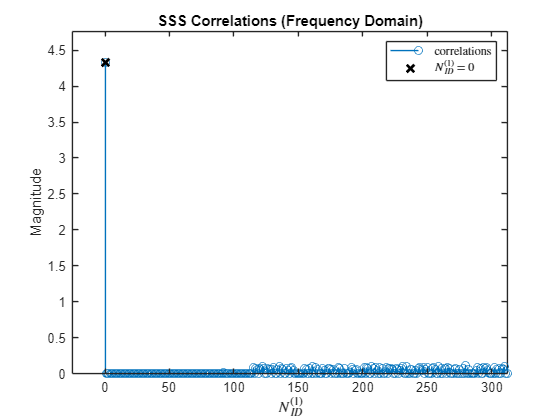

% Extract the received SSS symbols from the SS/PBCH block
sssIndices = nrSSSIndices;
sssRx = nrExtractResources(sssIndices,rxGrid);

% Correlate received SSS symbols with each possible SSS sequence
sssEst = zeros(1,336);
for NID1 = 0:335

    ncellid = (3*NID1) + NID2;
    sssRef = nrSSS(ncellid);
    sssEst(NID1+1) = sum(abs(mean(sssRx .* conj(sssRef),1)).^2);

end

% Plot SSS correlations
figure;
stem(0:335,sssEst,'o');
title('SSS Correlations (Frequency Domain)');
xlabel('$N_{ID}^{(1)}$','Interpreter','latex');
ylabel('Magnitude');
axis([-1 336 0 max(sssEst)*1.1]);

% Determine NID1 by finding the strongest correlation
NID1 = find(sssEst==max(sssEst)) - 1;

% Plot selected NID1
hold on;
plot(NID1,max(sssEst),'kx','LineWidth',2,'MarkerSize',8);
legend(["correlations" "$N_{ID}^{(1)}$ = " + num2str(NID1)],'Interpreter','latex');

xlim([-25 312])


% Form overall cell identity from estimated NID1 and NID2
ncellid = (3*NID1) + NID2;

disp([' Cell identity: ' num2str(ncellid)])

 Cell identity: 1


## Primary Broadcast Channel Processing

the receiver constructs each possible PBCH DM-RS sequence and performs channel and noise estimation. The index of the PBCH DM-RS with the best SNR determines the LSBs of the SS/PBCH block index required for PBCH scrambling initialization.

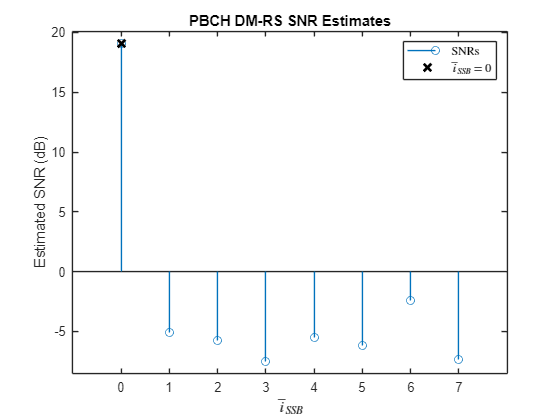

% Calculate PBCH DM-RS indices
dmrsIndices = nrPBCHDMRSIndices(ncellid);

% Perform channel estimation using DM-RS symbols for each possible DM-RS
% sequence and estimate the SNR
dmrsEst = zeros(1,8);
for ibar_SSB = 0:7

    refGrid = zeros([240 4]);
    refGrid(dmrsIndices) = nrPBCHDMRS(ncellid,ibar_SSB);
    [hest,nest] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);
    dmrsEst(ibar_SSB+1) = 10*log10(mean(abs(hest(:).^2)) / nest);

end

% Plot PBCH DM-RS SNRs
figure;
stem(0:7,dmrsEst,'o');
title('PBCH DM-RS SNR Estimates');
xlabel('$\overline{i}_{SSB}$','Interpreter','latex');
xticks(0:7);
ylabel('Estimated SNR (dB)');
axis([-1 8 min(dmrsEst)-1 max(dmrsEst)+1]);

% Record ibar_SSB for the highest SNR
ibar_SSB = find(dmrsEst==max(dmrsEst)) - 1;

% Plot selected ibar_SSB
hold on;
plot(ibar_SSB,max(dmrsEst),'kx','LineWidth',2,'MarkerSize',8);
legend(["SNRs" "$\overline{i}_{SSB}$ = " + num2str(ibar_SSB)],'Interpreter','latex');

refGrid = zeros([nrbSSB*12 4]);
refGrid(dmrsIndices) = nrPBCHDMRS(ncellid,ibar_SSB);
refGrid(sssIndices) = nrSSS(ncellid);
[hest,nVar,hestInfo] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);

## PBCH Demodulation

disp(' -- PBCH demodulation and BCH decoding -- ')

 -- PBCH demodulation and BCH decoding -- 


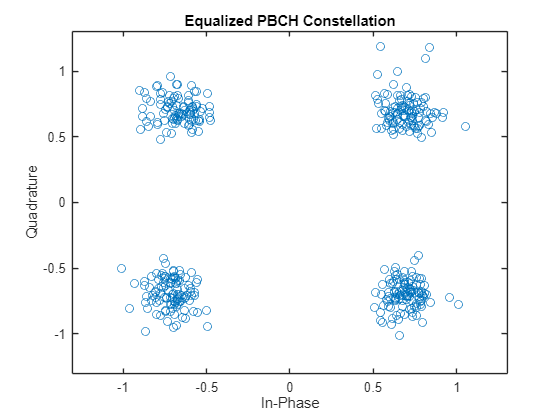


% Extract the received PBCH symbols from the SS/PBCH block
[pbchIndices,pbchIndicesInfo] = nrPBCHIndices(ncellid);
pbchRx = nrExtractResources(pbchIndices,rxGrid);

% Configure 'v' for PBCH scrambling according to TS 38.211 Section 7.3.3.1
% 'v' is also the 2 LSBs of the SS/PBCH block index for L_max=4, or the 3
% LSBs for L_max=8 or 64.
if refBurst.L_max == 4
    v = mod(ibar_SSB,4);
else
    v = ibar_SSB;
end
ssbIndex = v;

% PBCH equalization and CSI calculation
pbchHest = nrExtractResources(pbchIndices,hest);
[pbchEq,csi] = nrEqualizeMMSE(pbchRx,pbchHest,nVar);
Qm = pbchIndicesInfo.G / pbchIndicesInfo.Gd;
csi = repmat(csi.',Qm,1);
csi = reshape(csi,[],1);

% Plot received PBCH constellation after equalization
figure;
plot(pbchEq,'o');
xlabel('In-Phase'); ylabel('Quadrature')
title('Equalized PBCH Constellation');
m = max(abs([real(pbchEq(:)); imag(pbchEq(:))])) * 1.1;
axis([-m m -m m]);

% xlim([-1.51 1.32])
% ylim([-1.40 1.42])
% PBCH demodulation
pbchBits = nrPBCHDecode(pbchEq,ncellid,v,nVar);

% Calculate RMS PBCH EVM
pbchRef = nrPBCH(pbchBits<0,ncellid,v);
evm = comm.EVM;
pbchEVMrms = evm(pbchRef,pbchEq);

% Display calculated EVM
disp([' PBCH RMS EVM: ' num2str(pbchEVMrms,'%0.3f') '%']);

 PBCH RMS EVM: 14.591%


## BCH Decoding

% Apply CSI
pbchBits = pbchBits .* csi;

% Perform BCH decoding including rate recovery, polar decoding, and CRC
% decoding. PBCH descrambling and separation of the BCH transport block
% bits 'trblk' from 8 additional payload bits A...A+7 is also performed:
%   A ... A+3: 4 LSBs of system frame number
%         A+4: half frame number
% A+5 ... A+7: for L_max=64, 3 MSBs of the SS/PBCH block index
%              for L_max=4 or 8, A+5 is the MSB of subcarrier offset k_SSB
polarListLength = 8;
[~,crcBCH,trblk,sfn4lsb,nHalfFrame,msbidxoffset] = ...
    nrBCHDecode(pbchBits,polarListLength,refBurst.L_max,ncellid);

% Display the BCH CRC
disp([' BCH CRC: ' num2str(crcBCH)]);

 BCH CRC: 0



% Stop processing MIB and SIB1 if BCH was received with errors
if crcBCH
    disp(' BCH CRC is not zero.');
    return
end

% Use 'msbidxoffset' value to set bits of 'k_SSB' or 'ssbIndex', depending
% on the number of SS/PBCH blocks in the burst
if (refBurst.L_max==64)
    ssbIndex = ssbIndex + (bit2int(msbidxoffset,3) * 8);
    k_SSB = 0;
else
    k_SSB = msbidxoffset * 16;
end

% Displaying the SSB index
disp([' SSB index: ' num2str(ssbIndex)])

 SSB index: 0


## MIB and BCH Parsing

 Parses the 24 decoded BCH transport block bits into a MIB message and creates the `initialSystemInfo` structure with initial system information. 

% Parse the last 23 decoded BCH transport block bits into a MIB message.
% The BCH transport block 'trblk' is the RRC message BCCH-BCH-Message,
% consisting of a leading 0 bit and 23 bits corresponding to the MIB. The
% leading bit signals the message type transmitted (MIB or empty sequence).

mib = fromBits(MIB,trblk(2:end)); % Do not parse leading bit

% Create a structure containing complete initial system information
initialSystemInfo = initSystemInfo(mib,sfn4lsb,k_SSB,refBurst.L_max);

% Display the MIB structure
disp(' BCH/MIB Content:')

 BCH/MIB Content:


% Expected Output according to Config
%                      NFrame: 0
%     SubcarrierSpacingCommon: 30
%                       k_SSB: 12
%           DMRSTypeAPosition: 2
%             PDCCHConfigSIB1: [1×1 struct]
%                  CellBarred: 0
%        IntraFreqReselection: 0
disp(initialSystemInfo);

                     NFrame: 0
    SubcarrierSpacingCommon: 30
                      k_SSB: 12
          DMRSTypeAPosition: 2
            PDCCHConfigSIB1: [1×1 struct]
                 CellBarred: 0
       IntraFreqReselection: 0



## Local Funcs

function present = isCORESET0Present(ssbBlockPattern,kSSB)

    switch ssbBlockPattern
        case {'Case A','Case B','Case C'} % FR1
            kssb_max = 23;
        case {'Case D','Case E'} % FR2
            kssb_max = 11;
    end
    if (kSSB <= kssb_max)
        present = true;
    else
        present = false;
    end

end

function [timingOffset,nLeadingFrames] = hTimingOffsetToFirstFrame(offset,burst,ssbIdx,nHalfFrame,sampleRate)

    % As the symbol lengths are measured in FFT samples, scale the symbol
    % lengths to account for the receiver sample rate. Non-integer delays
    % are approximated at the end of the process.
    scs = hSSBurstSubcarrierSpacing(burst.BlockPattern);
    ofdmInfo = nrOFDMInfo(1,scs,'SampleRate',sampleRate); % smallest FFT size for SCS-SR
    srRatio = sampleRate/(scs*1e3*ofdmInfo.Nfft);
    symbolLengths = ofdmInfo.SymbolLengths*srRatio;

    % Adjust timing offset to the start of the SS block. This step removes
    % the extra offset introduced in the reference grid during PSS search,
    % which contained the PSS in the second OFDM symbol.
    offset = offset + symbolLengths(1);

    % Timing offset is adjusted so that the received grid starts at the
    % frame head i.e. adjust the timing offset for the difference between
    % the first symbol of the strongest SSB, and the start of the frame
    burstStartSymbols = hSSBurstStartSymbols(burst.BlockPattern,burst.L_max); % Start symbols in SSB numerology
    ssbFirstSym = burstStartSymbols(ssbIdx+1); % 0-based

    % Adjust for whole subframes
    symbolsPerSubframe = length(symbolLengths);
    subframeOffset = floor(ssbFirstSym/symbolsPerSubframe);
    samplesPerSubframe = sum(symbolLengths);
    timingOffset = offset - (subframeOffset*samplesPerSubframe);

    % Adjust for remaining OFDM symbols
    symbolOffset = mod(ssbFirstSym,symbolsPerSubframe);
    timingOffset = timingOffset - sum(symbolLengths(1:symbolOffset));

    % The first OFDM symbol of the SSB is defined with respect to the
    % half-frame where it is transmitted. Adjust for half-frame offset
    timingOffset = timingOffset - nHalfFrame*5*samplesPerSubframe;

    % Adjust offset to the first frame in the waveform that is scheduled
    % for SSB transmission.
    repetitions = ceil(timingOffset/(20*samplesPerSubframe));
    timingOffset = round(timingOffset - repetitions*20*samplesPerSubframe);

    % Calculate the number of leading frames before the detected one
    nLeadingFrames = 2*repetitions;

end

function initSystemInfo = initSystemInfo(mib,sfn4lsb,k_SSB,L_max)

    % Create set of subcarrier spacings signaled by the 7th bit of the
    % decoded MIB, the set is different for FR1 (L_max=4 or 8) and FR2
    % (L_max=64)
    if (L_max==64)
        scsCommon = [60 120];
    else
        scsCommon = [15 30];
    end

    initSystemInfo = struct();
    initSystemInfo.NFrame = mib.systemFrameNumber*2^4 + bit2int(sfn4lsb,4);
    initSystemInfo.SubcarrierSpacingCommon = scsCommon(mib.subCarrierSpacingCommon + 1);
    initSystemInfo.k_SSB = k_SSB + mib.ssb_SubcarrierOffset;
    initSystemInfo.DMRSTypeAPosition = 2 + mib.dmrs_TypeA_Position;
    initSystemInfo.PDCCHConfigSIB1 = info(mib.pdcch_ConfigSIB1);
    initSystemInfo.CellBarred = mib.cellBarred;
    initSystemInfo.IntraFreqReselection = mib.intraFreqReselection;

end

function nrb = hCORESET0DemodulationBandwidth(sysInfo,scsSSB,minChannelBW)

    % Determine the OFDM demodulation bandwidth from CORESET 0 bandwidth
    cset0Idx = sysInfo.PDCCHConfigSIB1.controlResourceSetZero;
    scsCommon = sysInfo.SubcarrierSpacingCommon;
    scsPair = [scsSSB scsCommon];
    [csetNRB,~,csetFreqOffset] = hCORESET0Resources(cset0Idx,scsPair,minChannelBW,sysInfo.k_SSB);

    % Calculate a suitable bandwidth in RB that includes CORESET 0 in
    % received waveform.
    c0 = csetFreqOffset + 10*scsSSB/scsCommon;  % CORESET frequency offset from carrier center
    nrb = 2*max(c0,csetNRB-c0)+2;               % Number of RB to cover CORESET 0

end

function [k,slots,slotSymbols,ssStartSym] = hPDCCH0MonitoringResources(systemInfo,scsSSB,minChannelBW,ssbIndex,numRxSym)

    cset0Idx = systemInfo.PDCCHConfigSIB1.controlResourceSetZero;
    scsCommon = systemInfo.SubcarrierSpacingCommon;
    scsPair = [scsSSB scsCommon];
    k_SSB = systemInfo.k_SSB;
    [c0NRB,c0Duration,c0FreqOffset,c0Pattern] = hCORESET0Resources(cset0Idx,scsPair,minChannelBW,k_SSB);

    ssIdx = systemInfo.PDCCHConfigSIB1.searchSpaceZero;
    [ssSlot,ssStartSym,isOccasion] = hPDCCH0MonitoringOccasions(ssIdx,ssbIndex,scsPair,c0Pattern,c0Duration,systemInfo.NFrame);

    % PDCCH monitoring occasions associated to different SS blocks can be
    % in different frames. If there are no monitoring occasions in this
    % frame, there must be one in the next one. Adjust the slots associated
    % to the search space by one frame if needed.
    slotsPerFrame = 10*scsCommon/15;
    ssSlot = ssSlot + (~isOccasion)*slotsPerFrame;

    % For FR1, UE monitors PDCCH in the Type0-PDCCH CSS over two consecutive
    % slots for CORESET pattern 1
    monSlotsPerPeriod = 1 + (c0Pattern==1);

    % Calculate 1-based subscripts of the subcarriers and OFDM symbols for
    % the slots containing the PDCCH0 associated to the detected SS block
    % in this and subsequent 2-frame blocks
    nrb = hCORESET0DemodulationBandwidth(systemInfo,scsSSB,minChannelBW);
    k = 12*(nrb-20*scsSSB/scsCommon)/2 - c0FreqOffset*12 + (1:c0NRB*12);

    symbolsPerSlot = 14;
    numRxSlots = ceil(numRxSym/symbolsPerSlot);
    slots = ssSlot + (0:monSlotsPerPeriod-1)' + (0:2*slotsPerFrame:(numRxSlots-ssSlot-1));
    slots = slots(:)';
    slotSymbols = slots*symbolsPerSlot + (1:symbolsPerSlot)';
    slotSymbols = slotSymbols(:)';

    % Remove monitoring symbols exceeding waveform limits
    slotSymbols(slotSymbols>numRxSym) = [];

    % Calculate the monitoring slots after removing symbols
    slots = (slotSymbols(1:symbolsPerSlot:end)-1)/symbolsPerSlot;

end

function scsKSSB = kSSBSubcarrierSpacing(scsCommon)
% Subcarrier spacing of k_SSB, as defined in TS 38.211 Section 7.4.3.1

    if scsCommon > 30  % FR2
        scsKSSB = scsCommon;
    else
        scsKSSB = 15;
    end

end

function c = hCarrierConfigSIB1(ncellid,initSystemInfo,pdcch)

    c = nrCarrierConfig;
    c.SubcarrierSpacing = initSystemInfo.SubcarrierSpacingCommon;
    c.NStartGrid = pdcch.NStartBWP;
    c.NSizeGrid = pdcch.NSizeBWP;
    c.NSlot = pdcch.SearchSpace.SlotPeriodAndOffset(2);
    c.NFrame = initSystemInfo.NFrame;
    c.NCellID = ncellid;

end

function plotResourceGrid(rxGrid,refBurst,systemInfo,nLeadingFrames,ssbIndex,nHalfFrame)

    % Extract SSB and common SCS from reference SS burst and initial system
    % information
    scsSSB = hSSBurstSubcarrierSpacing(refBurst.BlockPattern);
    scsCommon = systemInfo.SubcarrierSpacingCommon;
    scsRatio = scsSSB/scsCommon;

    % Number of subcarriers, symbols and frames.
    [K,L] = size(rxGrid);
    symbolsPerSubframe = 14*scsCommon/15;
    numFrames = ceil(L/(10*symbolsPerSubframe));

    % Define colors and auxiliary plotting function
    basePlotProps = {'LineStyle','-','LineWidth',1};
    occasionColor = 0.7*[1 1 1];
    detectionColor = [200,0,0]/255;

    frameBoundaryColor = 0.1*[1 1 1];
    boundingBox = @(y,x,h,w,varargin)rectangle('Position',[x+0.5 y-0.5 w h],basePlotProps{:},varargin{:});

    % Create figure and display resource grid
    figure;
    imagesc(abs(rxGrid(:,:,1))); axis xy; hold on;

    % Add vertical frame lines
    x = repmat((0:numFrames-1)*10*symbolsPerSubframe,3,1);
    x(3,:) = NaN;
    y = repmat([0;K;NaN],1,numFrames);
    plot(x(:),y(:),'Color',frameBoundaryColor);

    % Determine frequency origin of the SSB in common numerology
    ssbCenter = K/2;
    halfSSB = 10*12*scsRatio;
    scsKSSB = kSSBSubcarrierSpacing(scsCommon);
    kSSBFreqOff = systemInfo.k_SSB*scsKSSB/scsCommon;
    ssbFreqOrig = ssbCenter - halfSSB + kSSBFreqOff + 1;

    % Determine time origin of the SSB in common numerology
    ssbStartSymbols = hSSBurstStartSymbols(refBurst.BlockPattern,refBurst.L_max);
    ssbStartSymbols = ssbStartSymbols + 5*symbolsPerSubframe*nHalfFrame;
    ssbHeadSymbol = ssbStartSymbols(ssbIndex+1)/scsRatio;
    ssbTailSymbol = floor((ssbStartSymbols(ssbIndex+1)+4)/scsRatio)-1;

    % Draw bounding boxes around all SS/PBCH block occasions
    w = ssbTailSymbol - ssbHeadSymbol + 1;
    for i = 1:ceil(numFrames/2)
        s = ssbHeadSymbol + (i-1)*2*10*symbolsPerSubframe + 5*symbolsPerSubframe*nHalfFrame;
        if s <= (L - w)
            boundingBox(ssbFreqOrig,s,240*scsRatio,w,'EdgeColor',occasionColor);
        end
    end

    % Draw bounding box for detected SS/PBCH block
    s = ssbHeadSymbol + nLeadingFrames*10*symbolsPerSubframe + 5*symbolsPerSubframe*nHalfFrame;
    boundingBox(ssbFreqOrig,s,240*scsRatio,w,basePlotProps{:},'EdgeColor',detectionColor)

    % Add text next to detected SS/PBCH block
    str = sprintf('SSB#%d',ssbIndex);
    text(s+w+1,ssbFreqOrig+24,0,str,'FontSize',10,'Color','w')

    % Create legend. Since rectangles don't show up in legend, create a
    % placeholder for bounding boxes.
    plot(NaN,NaN,basePlotProps{:},'Color',occasionColor);
    plot(NaN,NaN,basePlotProps{:},'Color',detectionColor);
    legend('Frame boundary','Occasion','Detected')
    xlabel('OFDM symbol'); ylabel('Subcarrier');

    % Add title including frame numbers
    firstNFrame = systemInfo.NFrame - nLeadingFrames;
    nframes = mod(firstNFrame + (0:numFrames-1),1024);
    sfns = sprintf('(%d...%d)',nframes(1),nframes(end));
    title(['Received Resource Grid. System Frame Number: ' sfns]);

end

function highlightCORESET0SS(csetSubcarriers,monSlots,detSlot,pdcch,dciCRC)

    ssFirstSym = pdcch.SearchSpace.StartSymbolWithinSlot;
    csetDuration = pdcch.CORESET.Duration;

    % Define colors and plotting function
    basePlotProps = {'LineStyle','-','LineWidth',1};
    occasionColor = 0.7*[1 1 1];
    detectionColor = [200,0,0]/255;
    boundingBox = @(y,x,h,w,varargin)rectangle('Position',[x+0.5 y-0.5 w h],basePlotProps{:},varargin{:});

    % Highlight all CORESET 0/SS occasions related to the detected SSB
    k0 = csetSubcarriers(1);
    K = length(csetSubcarriers);
    ssSym = 14*monSlots + ssFirstSym ;
    for i = 1:length(ssSym)
        boundingBox(k0,ssSym(i),K,csetDuration,'EdgeColor',occasionColor);
    end

    if dciCRC == 0
        % Highlight decoded PDCCH
        ssSym = 14*detSlot + ssFirstSym;
        boundingBox(k0,ssSym,K,csetDuration,'EdgeColor',detectionColor);

        % Add text next to decoded PDCCH
        text(ssSym+csetDuration+1,k0+24,0,'PDCCH','FontSize',10,'Color','w')
    end

end

function plotResourceGridSIB1(slotGrid,carrier,pdcch,pdsch,tcr,K0)

    % Display the OFDM grid of the slot containing decoded PDCCH
    figure;
    imagesc(abs(slotGrid(:,:,1))); axis xy
    xlabel('OFDM symbol');
    ylabel('subcarrier');
    title('Slot Containing Decoded PDCCH');

    aggregationLevelIndex = log2(pdcch.AggregationLevel)+1;
    candidate = pdcch.AllocatedCandidate;

    % Define auxiliary plotting function
    color = [200,0,0]/255;
    boundingBox = @(y,x,h,w,varargin)rectangle('Position',[x+0.5 y-0.5 w h],'EdgeColor',color,varargin{:});

    % Highlight PDCCH in resource grid
    carrier.NSlot = carrier.NSlot - K0; % Subtract slot offset K0 for subscripts calculations
    subsPdcch = nrPDCCHSpace(carrier,pdcch,'IndexStyle','Subs');
    subsPdcch = double(subsPdcch{aggregationLevelIndex}(:,:,candidate));
    x = min(subsPdcch(:,2))-1; X = max(subsPdcch(:,2))-x;
    y = min(subsPdcch(:,1)); Y = max(subsPdcch(:,1))-y+1;
    boundingBox(y,x,Y,X);
    str = sprintf('PDCCH \nAggregation Level: %d\nCandidate: %d',2.^(aggregationLevelIndex-1),candidate-1);
    text(x+X+1,y+Y/2,0,str,'FontSize',10,'Color','w')

    % Highlight PDSCH and PDSCH DM-RS in resource grid
    carrier.NSlot = carrier.NSlot + K0; % Add back slot offset K0 for subscripts calculations
    subsPdschSym = double(nrPDSCHIndices(carrier,pdsch,'IndexStyle','subscript'));
    subsPdschDmrs = double(nrPDSCHDMRSIndices(carrier,pdsch,'IndexStyle','subscript'));
    subsPdsch = [subsPdschSym;subsPdschDmrs];
    x = min(subsPdsch(:,2))-1; X = max(subsPdsch(:,2))-x;
    y = min(subsPdsch(:,1)); Y = max(subsPdsch(:,1))-y+1;
    boundingBox(y,x,Y,X);
    str = sprintf('PDSCH (SIB1) \nModulation: %s\nCode rate: %.2f',pdsch.Modulation,tcr);
    text(x+4,y+Y+60,0, str,'FontSize',10,'Color','w')

end

function [noise,nPowerPerRE] = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB), which is the
% receiver SNR per RE and antenna, assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power by the IFFT size used in OFDM modulation, as
    % the OFDM modulator applies this normalization to the transmitted
    % waveform. Also normalize by the number of receive antennas, as the
    % channel model applies this normalization to the received waveform by
    % default. The SNR is defined per RE for each receive antenna (TS
    % 38.101-4).
    SNR = 10^(SNRdB/10); % Calculate linear noise gain
    N0 = 1/sqrt(nRxAnts*double(Nfft)*SNR);
    noise = N0*randn(sizeRxWaveform,"like",1i);
    nPowerPerRE = N0^2*double(Nfft);
end
    
function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;

    % Set channel response output type to calculate perfect channel
    % estimation
    chClone.ChannelResponseOutput = 'ofdm-response';
    
    % Get perfect channel estimate directly from the channel
    estChannelGrid = chClone(carrier);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end

function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate.

    % Linearize 4-D matrix and reshape after multiplication
    K = size(estChannelGrid,1);
    L = size(estChannelGrid,2);
    R = size(estChannelGrid,3);
    estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
    estChannelGrid = estChannelGrid*W;
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end